%constant
c=60;
round=60;
l_veh=7;

E1=9;
E2=13;
E3=5;

%discrete green light time set

u_options=[15,20,25,30,35,40,45];
% u_options=15:1:45;

stopping_delta=1;



%initial start point
u0_5_5_2=u_options(randi(length(u_options))) % k=0

u0_5_5_2 = 25

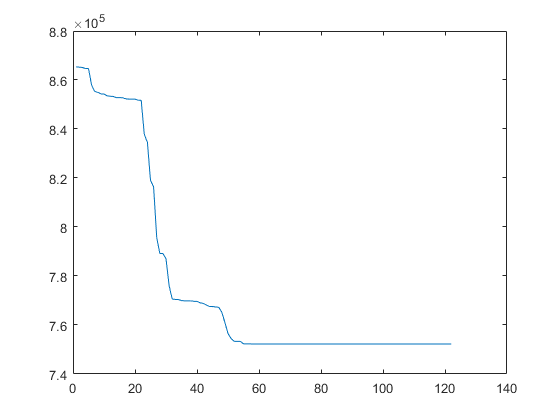

u_5_5_2=u_options(randi(length(u_options),[1,round]));
% u_5_5_2=30*ones(1,60);


[u0_optimal,u_optimal_5_5_2,TTS_optimal_history_5_5_2]=perpendicular_search(u0_5_5_2,u_5_5_2,u_options,stopping_delta,round);
plot(TTS_optimal_history_5_5_2)

TTS_optimal_history_5_5_2(end)

ans = 7.5226e+05

u_optimal_5_5_2

u_optimal_5_5_2 =     20    25    25    30    25    25    25    25    25    25    25    25    25    30    25    25    25    30    25    25    30    30    30    30    30    30    30    30    30    30    30    30    35    25    25    25    35    25    35    25    25    25    25    30    25    25    30    30    35    35


function [u0_optimal,u_optimal,TTS_min_history]=perpendicular_search(u0,u,u_options,stopping_delta,round)
    %iteration
    delta=2;
%     temp_u0=0;
%     temp_u=zeros(1,round)
    u0_optimal=u0;
    u_optimal=u;
    TTS=[];

    TTS_optimal = TTS_calculate(u0,u);
    while (delta>=stopping_delta)
    % for r=1:1:5
        for k = 1:1:round+1
            %choose perpendicular search direction
            temp_u=u_optimal;
            direction(k)=1;
            
            %choose the step
            if k==1
               for i= 1:1:length(u_options)
                    temp_u0=u_options(i);
                    [temp_TTS] = TTS_calculate(temp_u0,temp_u);
                    
                    if temp_TTS <TTS_optimal
                        u0_optimal=temp_u0;
                        TTS_optimal=temp_TTS;
                    end        
                end         
                TTS=[TTS,TTS_optimal];
            else
                for i= 1:1:length(u_options)
                    temp_u(k-1)=u_options(i);
                    temp_TTS = TTS_calculate(temp_u0,temp_u);
                    if temp_TTS <TTS_optimal
                        u_optimal=temp_u;
                        TTS_optimal=temp_TTS;
                    end    
                end
                TTS=[TTS,TTS_optimal];
            end
            direction(k)=0;
        end
        delta=abs(TTS(end)-TTS(end-round));
    end
    TTS_min_history=TTS;
end




